# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:8
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.1)

phases =          0    1.9635    3.3379    4.1233    4.1233    3.3379    1.9635         0
    1.9635    4.1233    5.4978    6.1850    6.1850    5.4978    4.1233    1.9635
    3.3379    5.4978    0.5890    1.3744    1.3744    0.5890    5.4978    3.3379
    4.1233    6.1850    1.3744    2.0617    2.0617    1.3744    6.1850    4.1233
    4.1233    6.1850    1.3744    2.0617    2.0617    1.3744    6.1850    4.1233
    3.3379    5.4978    0.5890    1.3744    1.3744    0.5890    5.4978    3.3379
    1.9635    4.1233    5.4978    6.1850    6.1850    5.4978    4.1233    1.9635
         0    1.9635    3.3379    4.1233    4.1233    3.3379    1.9635         0


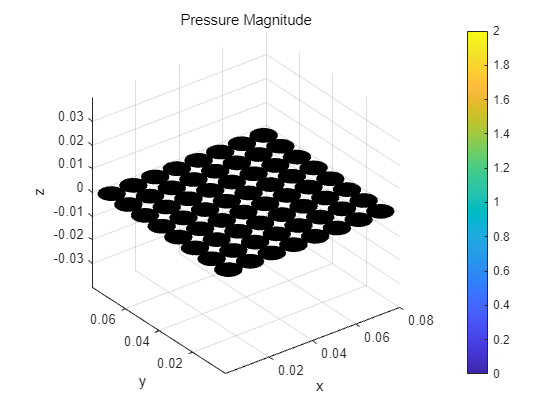

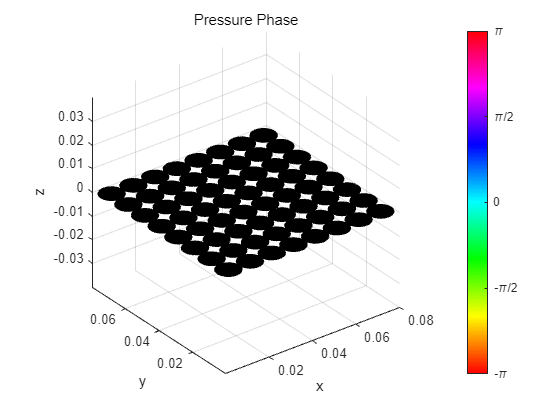

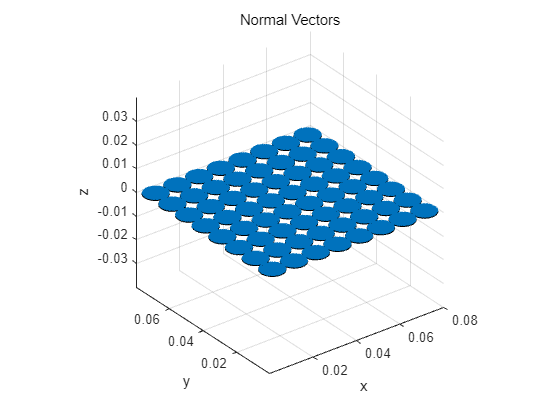

% phases = PFC_PhaseCalculate([0.02, 0.12], [8,8], 0.2)

% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:8
    for j = 1:8
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]

## Simulation Space

reading_pos_x = -20e-3 : 0.5e-3 : 100e-3;          % Simulation Area
reading_pos_y = -20e-3 : 0.5e-3 : 100e-3;          % Simulation Area
reading_pos_z = 0e-3 : 0.5e-3 : 150e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.04, reading_pos_z);

Started at 2024-08-05 23:24:20
Finished at 2024-08-05 23:25:12
Progressed time : 00:00:52


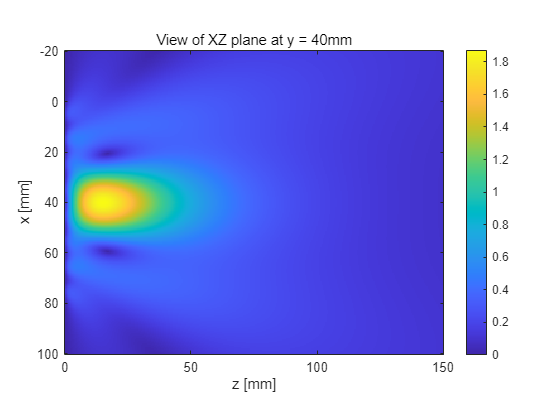


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 40mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 1.8723

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.2);

Started at 2024-08-05 23:25:13
Finished at 2024-08-05 23:25:57
Progressed time : 00:00:43


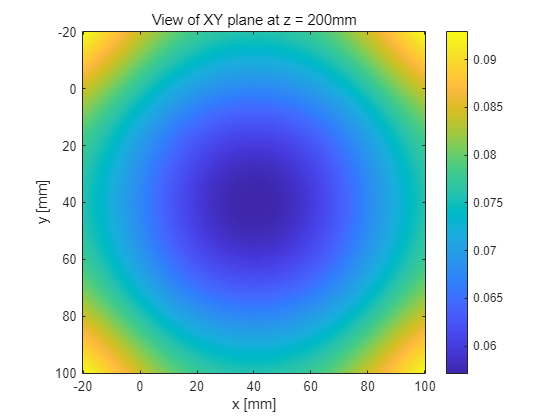


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 200mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 0.0930